## TIRF pipleine walkthrough

- Import ND2 file

- Find params for processing

- Batch process files to get intensity traces

- Analyze traces

%import a sample datafile
pathlist = getFileList(); % gets a list of datafiles that you specify in a filebrowser

processed_videos = processND2(pathlist,[-100 -50], true, [], [], [], 10); % imports list of ND2 files with the bioformats reader, returns a 5D array: [x, y, z, c, t]

Reading series #1
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ........................................................................
    ..............
--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------
--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------
Done with /home/colin/dat

Probably should separate import and backgrounding from LoGMask and have the user do them separately since we'll need the raw data later anyways.

processed_videos = LoGMask(processed_videos, [-300 -50], [], [], 10, [8 30]);

--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------
--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------
--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------
--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------
--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------
--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------
----------------------------------

That still needs a bit more work (try with some other data too? But lets move to overlap detection to see how that behaves.

processed_videos = batchFindOverlap(processed_videos,1,2,true,.6);

--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------
--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------
--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------
--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------
--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------
--------------------------------------------------------------
Status> ImageJ is already running.
--------------------------------------------------------------
----------------------------------

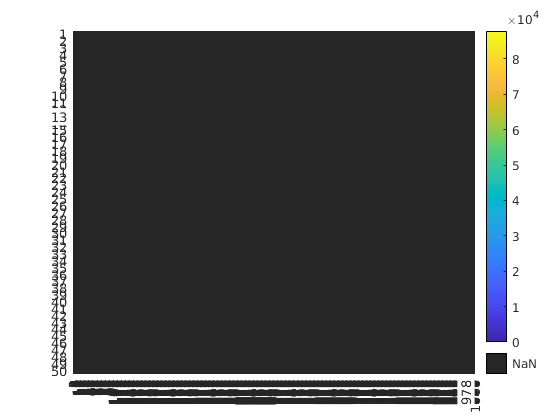

traces_p = batchGetTraces(processed_videos(5:8,:),5);
pHeatmap(traces_p(:,1,:));

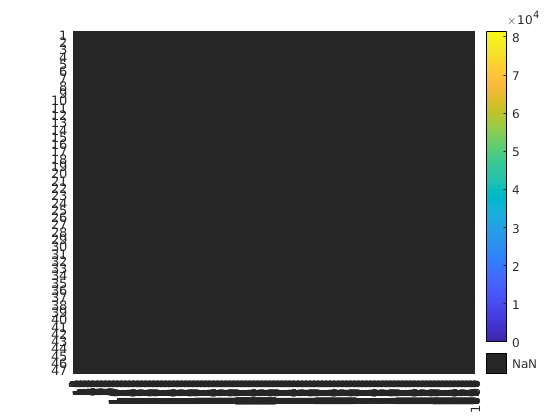


traces_n = batchGetTraces(processed_videos(1:4,:),5);
pHeatmap(traces_n(:,1,:));